## The Spread of an Infectious Disease

Jacob Wyngard

### My Model


$$X_{n+1} \sim \mathrm{Binomial}\left(\;\;\mathrm{Binomial}\left(N-X_n \;,\;\frac{X_n }{N}\right)+X_n \;,1-p\right)$$


### Expected Number of Infectious Individuals

Let $E_n$ be defined as the expected number of individuals at step *n*.

By the Law of Total Expectation,


$$E_{n+1} =2{\;E}_n \;\left(1-p\right)\;\left(1-\frac{E_n }{2N}\right)$$


The continuous form of this model is:


$$\frac{dE}{dn}=\;$$

$$2\;E\left(1-p\right)\;\left(1-\frac{E}{2N}\right)-E$$


As per Mathematica, given that *E[0] *=* A, *

$E_n =\frac{A\;{N\;\left(2p-1\right)\;e}^n \;}{N\;\left(2\;p-1\right){\;e}^{\;2p\;n} +\;{A\left(1-p\right)\;e}^{\;2p\;n} -A\;\left(1-p\right){\;e}^n }$ if $p\not= \frac{1}{2}$

If $p=\frac{1}{2},\;$$E_n =\frac{2\;A\;N}{A\;n+2N}$

I am very curious to see if this works!

% Set Up

function y2_array = y2_discrete(t,N,A,p)
    y2_array = zeros(1,t+1);
    y2_array(1) = A;

    for nn = 1:t
        y2_array(nn+1) = 2*y2_array(nn)*(1-p)*(1-y2_array(nn)/2/N);
    end

end


function y2_array = y2_continuous(t,N,A,p)
    y2_array = zeros(1,t+1);
    y2_array(1) = A;
    if p ~= .5
        for nn = 0:t
            numerator = A*N*(2*p-1)*exp(nn);
            denominator_term1 = N*(2*p-1)*exp(2*p*nn);
            denominator_term2 = A*(1-p)*exp(2*p*nn);
            denominator_term3 = A*(1-p)*exp(nn);
            denominator = denominator_term1 + denominator_term2 - denominator_term3;
            y2_array(nn+1) = numerator/denominator;
        end
    else
        for nn = 0:t
            numerator = 2*N;
            denominator = nn + 2*N/A;
            y2_array(nn+1) = numerator/denominator;
        end
    end
end

function y2_array = y2_experimental(t,N,A,p,num_trials)
    y2_array = zeros(num_trials,t+1);

    for trial_number = 1:num_trials
        is_infected = zeros(1,N); % Boolean Values of Whether Students are Infected
        for ii = 1:A
            is_infected(ii) = 1;
        end
    
        for ii = 1:(t+1)
            % Number of Infected at the End of Yesterday
            y2_array(trial_number,ii) = sum(is_infected);
    
            % Spread of Infection
            for student = 1:N
                if ~is_infected(student)
                    picked_person = randi(N);
                    if is_infected(picked_person)
                        is_infected(student) = 1;
                    end
                end
            end

            % Possibility of Recovery
            for student = 1:N
                if is_infected(student) 
                    r = rand();
                    if r < p
                        is_infected(student) = 0;
                    end
                end
            end

        end
    end

    y2_array = mean(y2_array);
end


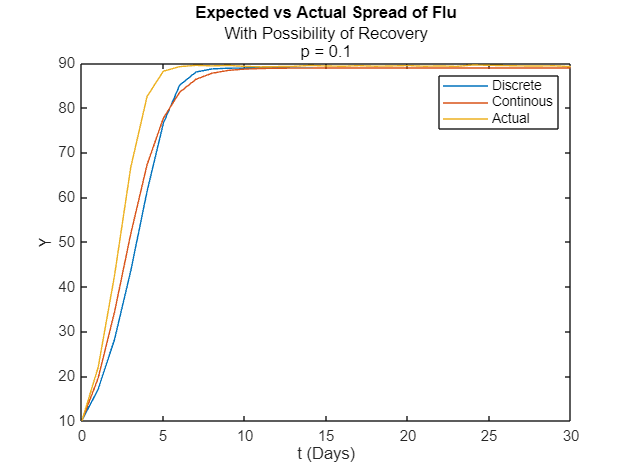

% Execution

N = 100; A = 10; t = 30;

% p = 0.1
p = 0.1;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

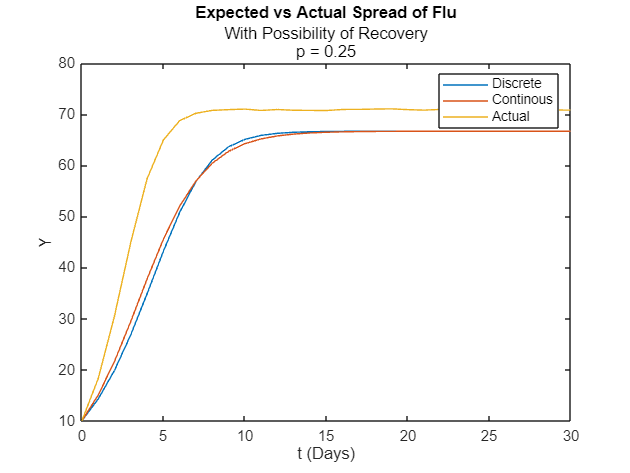


% p = .25
p = .25;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

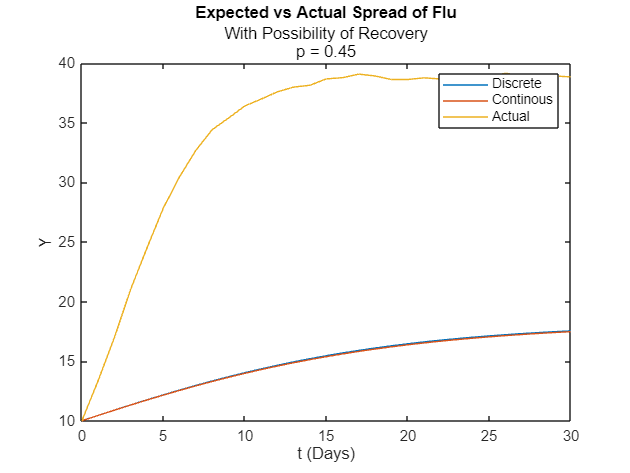


% p = .45
p = .45;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

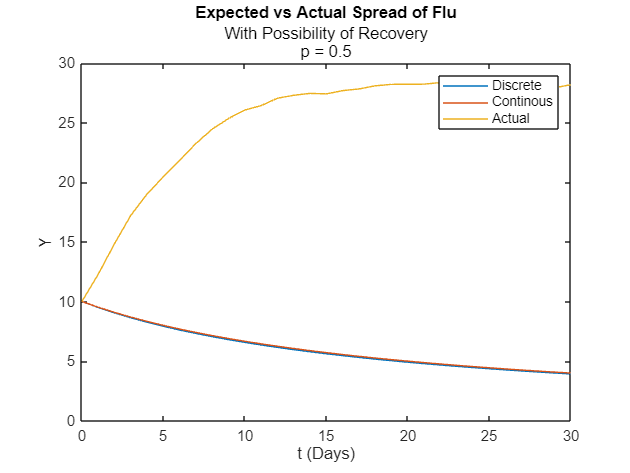


% p = .5
p = .5;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

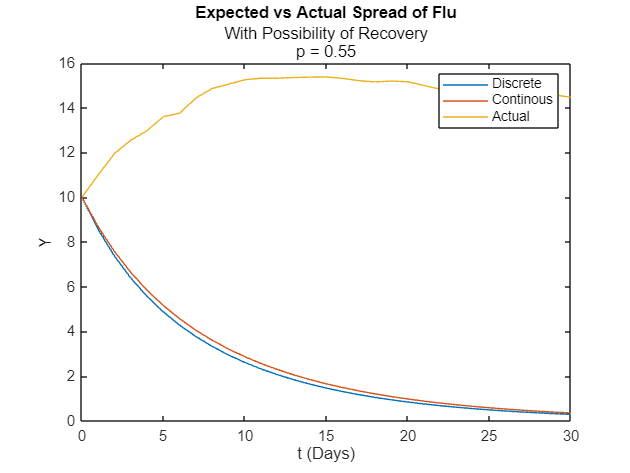


% p = .55
p = .55;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

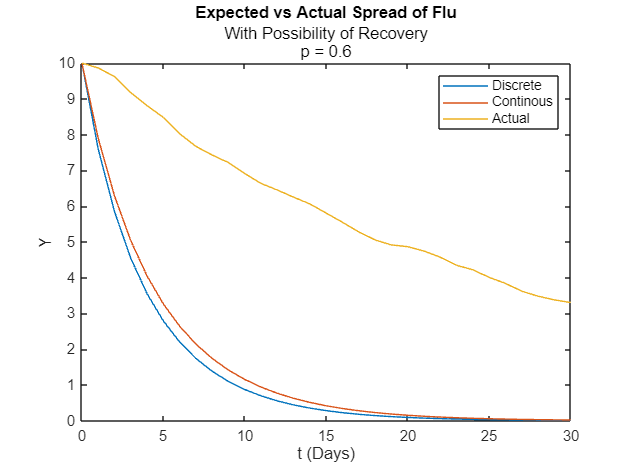


% p = .6
p = .6;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

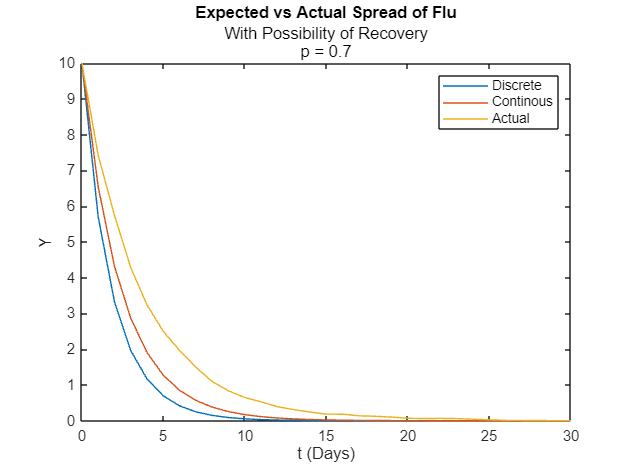


% p = .7
p = .7;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

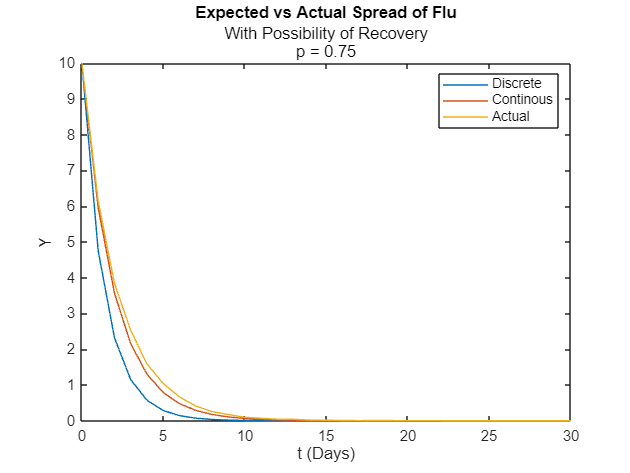


% p = .75
p = .75;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

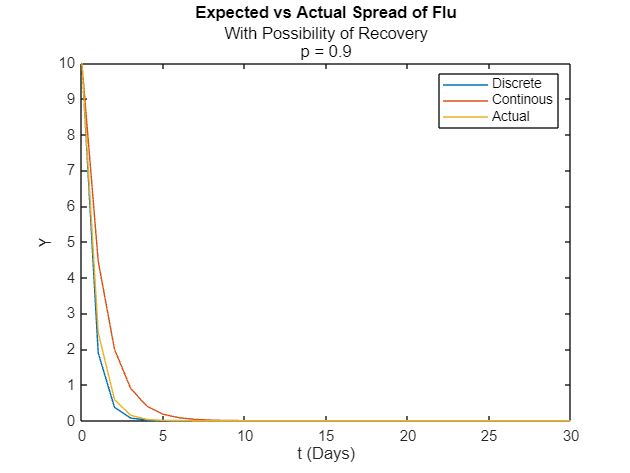


% p = .9
p = .9;

plot(0:t,y2_discrete(t,N,A,p))
hold on
plot(0:t,y2_continuous(t,N,A,p))
plot(0:t,y2_experimental(t,N,A,p,1000))
xlabel('t (Days)')
ylabel('Y')
title('Expected vs Actual Spread of Flu')
subtitle({'With Possibility of Recovery',sprintf('p = %.2g',p)})
legend({'Discrete','Continous','Actual'})
hold off

Well, the good news is that the discrete and continuous forms of my model work are approximately the same.

The bad news is that they only match the actual system for high values of p (p > .7)

### Variance in Total Infectious Individuals